## Proyecto 3 Estadística - Modelos de regresión

### Nicolas Vargas Flores 1001368855

### Jader Stalyn Chingall Atis

#### Universidad de Antioquia

## Primera parte - Análisis exploratorio de datos (AED)

Se carga la base de datos "`datos_state.csv`".

BD = readtable("datos_state.csv");

Para calculas las estadísticas descriptivas pertinentes al proyecto se utiliza la herramienta "*Compute by group*".

% Compute group summary
AED_stats = groupsummary(BD,"Life_Exp",1,["mean","median","mode","max","min", ...
    "std","var","nummissing"],true(1,9))

AED_stats = 1×74 table
    disc_Life_Exp    GroupCount    mean_Population    median_Population    mode_Population    max_Population    min_Population    std_Population    var_Population    nummissing_Population    mean_Income    median_Income    mode_Income    max_Income    min_Income    std_Income    var_Income    nummissing_Income    mean_Illiteracy    median_Illiteracy    mode_Illiteracy    max_Illiteracy    min_Illiteracy    std_Illiteracy    var_Illiteracy    nummissing_Illiteracy    mean_Life_Exp    median_Life_Exp

Con la información recopilada en "AED_stats" se procede a presentar las estadísticas de los datos.

varNames = AED_stats.Properties.VariableNames;

% La información se almacena en una tabla
statsTable = table('Size', [9 8], 'VariableTypes', repmat({'double'}, 1, 8), ...
    'VariableNames', {'Means', 'Medians', 'Modes', 'Maxs', 'Mins', 'Stds', 'Vars', ...
    'Nummissings'}, 'RowNames', {'Population', 'Illiteracy', 'Income', 'Life_Exp', ...
    'Murder', 'HS_Grad', 'Frost', 'Area', 'Density_pob'});

% Cada fila es una estadística de cada variable
for i = 1:length(varNames)
    if startsWith(varNames{i}, 'mean_')
        statsTable.('Means')(varNames{i}(6:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'median_')
        statsTable.('Medians')(varNames{i}(8:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'mode_')
        statsTable.('Modes')(varNames{i}(6:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'max_')
        statsTable.('Maxs')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'min_')
        statsTable.('Mins')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'std_')
        statsTable.('Stds')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'var_')
        statsTable.('Vars')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'nummissing_')
        statsTable.('Nummissings')(varNames{i}(12:end)) = AED_stats.(varNames{i});
    end
end

disp(statsTable)

                   Means     Medians     Modes        Maxs        Mins       Stds         Vars       Nummissings
                   ______    _______    _______    __________    _______    _______    __________    ___________

    Population     4246.4    2838.5         365         21198        365     4464.5    1.9932e+07         0     
    Illiteracy       1.17      0.95         0.6           2.8        0.5    0.60953       0.37153         0     
    Income         4435.8      4519        3098          6315       3098     614.47    3.7757e+05         0     
    Life_Exp       70.879    70.675       70.55          73.6      67.96     1.3424         1.

Para tener una vista general de los datos se realizan histogramas para cada variable.

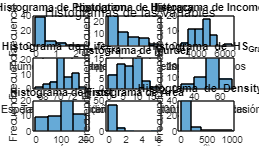

% Histogramas
variables = {'Population', 'Illiteracy', 'Income', 'Life_Exp', 'Murder', ...
    'HS_Grad', 'Frost', 'Area', 'Density_pob'};

figure;
for i = 1:length(variables)
    subplot(3, 3, i);
    histogram(BD.(variables{i}));
    title(['Histograma de ' variables{i}]);
    switch variables{i}
        case 'Population'
            xlabel('Número de habitantes');
        case 'Illiteracy'
            xlabel('Porcentaje de analfabetismo (%)');
        case 'Income'
            xlabel('Ingresos medios');
        case 'Life_Exp'
            xlabel('Esperanza de vida (años)');
        case 'Murder'
            xlabel('Tasa de homicidios por cada 100.000 habitantes');
        case 'HS_Grad'
            xlabel('Porcentaje de habitantes con educación universitaria (%)');
        case 'Frost'
            xlabel('Cantidad de días al año con heladas');
        case 'Area'
            xlabel('Área total de la ciudad (km^2)');
        case 'Density_pob'
            xlabel('Densidad de población (habitantes por km^2)');
    end
    ylabel('Frecuencia');
end
sgtitle('Histogramas de las Variables');
set(gcf, 'Position', get(0, 'Screensize')); % Maximiza la figura

Los siguientes diagramas de cajas y bigotes serán útiles para visualizar la distribución de la información, y ser conscientes de los posibles outliers que hay en cada variable.

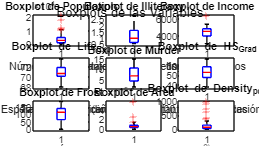

% Boxplots
figure;
for i = 1:length(variables)
    subplot(3, 3, i);
    boxplot(BD.(variables{i}));
    title(['Boxplot de ' variables{i}]);
    switch variables{i}
        case 'Population'
            xlabel('Número de habitantes');
        case 'Illiteracy'
            xlabel('Porcentaje de analfabetismo (%)');
        case 'Income'
            xlabel('Ingresos medios');
        case 'Life_Exp'
            xlabel('Esperanza de vida (años)');
        case 'Murder'
            xlabel('Tasa de homicidios por cada 100.000 habitantes');
        case 'HS_Grad'
            xlabel('Porcentaje de habitantes con educación universitaria (%)');
        case 'Frost'
            xlabel('Cantidad de días al año con heladas');
        case 'Area'
            xlabel('Área total de la ciudad (km^2)');
        case 'Density_pob'
            xlabel('Densidad de población (habitantes por km^2)');
    end
end
sgtitle('Boxplots de las Variables');
set(gcf, 'Position', get(0, 'Screensize')); % Maximiza la figura

### Distribuciones

Notese que en los diagramas anteriores se ve que existen muchos datos outliers que aumentan la varianza significativamente, lo cual hace que la normalidad de los datos se vea gravemente afectada. Con el propósito de encontrar una distribución estadística que nos sirva para realizar los posteriores análisis; se transforman los datos para atenuar el peso de los outliers dentro del desenlace estadístico.

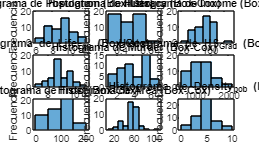

% Librería de estadísticas
import statistics.*

figure;
% Box-Cox transformation
for i = 1:length(variables)
    % Aplicar la transformación de Box-Cox
    [transformed, lambda] = boxcox(BD.(variables{i})+1);
    
    % Se almacenan los datos en una tabla
    BD.([variables{i} '_boxcox']) = transformed;
    
    % Histogramas con los datos transformados
    subplot(3, 3, i);
    histogram(transformed);
    title(['Histograma de ' variables{i} ' (Box-Cox)']);
    xlabel('Valor');
    ylabel('Frecuencia');
end
set(gcf, 'Position', get(0, 'Screensize'));

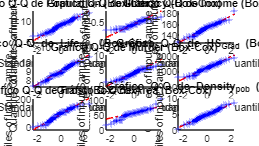


figure;
% Gráficos Q-Q para cada variable
for i = 1:length(variables)
    subplot(3, 3, i);
    qqplot(BD.([variables{i} '_boxcox']));
    title(['Gráfico Q-Q de ' variables{i} ' (Box-Cox)']);
end
set(gcf, 'Position', get(0, 'Screensize'));

La transformación de Box-Cox es una técnica estadística que se utiliza para transformar datos no normales en una forma que se aproxime a la normalidad. La transformación de Box-Cox se define como:

$y(\lambda )=\left\lbrace \begin{array}{ll}
\frac{y^{\lambda } -1}{\lambda } & \textrm{si}\;\lambda \not= 0,\\
\ln (y) & \textrm{si}\;\lambda =0,
\end{array}\right.$�

donde `y` es la variable que se desea transformar y `λ` es el parámetro de transformación. El valor de `λ` se elige de manera que maximice la verosimilitud de los datos transformados.

Para este estudio la transformación de Box-Cox es útil porque ayuda a estabilizar la varianza, hace que los datos se comporten más como una distribución normal, mejora la validez de las medidas de asociación (como la correlación) y hace que los patrones en los datos y los residuos sean más fáciles de identificar. Box-Cox es especialmente útil para manejar los valores atípicos.

### Contrastando la normalidad

Es importante conocer las distribuciones de los datos; especialmente conocer cuales de ellos tienen una distribución Gaussiana. Esta sección realizará una prueba de Shapiro-Wilk para cada variable para evaluar si los datos siguen una distribución normal. También se creará un gráfico Q-Q para cada variable, que es una herramienta gráfica para evaluar si un conjunto de datos proviene de una distribución teórica determinada, en este caso, una distribución normal.

La siguiente sección realiza gráficos Q-Q para cada variable con el fin de conocer si la distribución de estas (sin transformaciones) se acerca a una distribución normal.

results = table('Size', [length(variables) 4], ...
    'VariableTypes', {'string', 'logical', 'double', 'string'}, ...
    'VariableNames', {'Variable', 'H0_Rejected', 'P_Value', 'Distribution'});

% Se descargó prueba swtest.m en File Exchange MatLab
for i = 1:length(variables)
    % Aplicar la prueba de Shapiro-Wilk
    [h, p] = swtest(BD.([variables{i} '_boxcox']));
    
    % Determinar si los datos siguen una distribución normal
    if h == 0
        distribution = 'Gaussiana';
    else
        distribution = 'No Gaussiana';
    end
    
    results(i, :) = {variables{i}, h, p, distribution};
end

disp(results)

      Variable       H0_Rejected     P_Value      Distribution 
    _____________    ___________    _________    ______________

    "Population"        false         0.38817    "Gaussiana"   
    "Illiteracy"        true        0.0037886    "No Gaussiana"
    "Income"            false         0.33775    "Gaussiana"   
    "Life_Exp"          false         0.50064    "Gaussiana"   
    "Murder"            false        0.063933    "Gaussiana"   
    "HS_Grad"           false         0.13314    "Gaussiana"   
    "Frost"             true         0.045587    "No Gaussiana"
    "Area"              true        0.0074883    "No Gaussiana"
    "Density_pob"       false         0.87122    "Gaussiana"   



## Segunda parte - Estadística inferencial